# Spotting Swing Model

%[theta d a alpha sigma offset]
%theta [rad] angle of joint
%d length of prismatic componet
%a length of link
%alpha [rad] link twist angle
%sigma == 1 is prismatic  == 0 is revolute
%offset
link1 = Link( [ deg2rad(74.311), 0, 17.917, 0, 0, 0], 'standard' );
link1.qlim = pi/180 * [74.311-2 74.311+2];

link2 = Link( [ deg2rad(0), 0, 13.75, 0, 0, 0], 'standard' );
link2.qlim = pi/180 * [-2 2];

link3 = Link( [           0, 0,     0, 0, 1, 0], 'standard' );
link3.qlim = [0 4.75];

modelMasterX = SerialLink( [link1, link2, link3], 'name', 'masterX')

 
modelMasterX = 
 
masterX:: 3 axis, RRP, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|     17.917|          0|          0|
|  2|         q2|          0|      13.75|          0|          0|
|  3|          0|         q3|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


%inputs forward kinematics
spottingSWGCylinderExtension = 4.75/2 %limit is 0 to 4.75

spottingSWGCylinderExtension = 2.3750

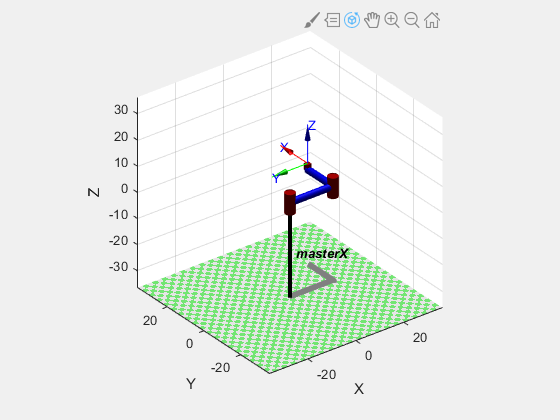

Tmaster = [deg2rad(0), deg2rad(90), spottingSWGCylinderExtension ];
modelMasterX.plot(Tmaster)


%input inverse kinematic
masterHoleX = 8.842

masterHoleX = 8.8420

height = 28.896 * sin( deg2rad(30.59) )

height = 14.7049

spottingSWGCylinderExtension = sqrt(masterHoleX * masterHoleX+height*height)-link2.a

spottingSWGCylinderExtension = 3.4085

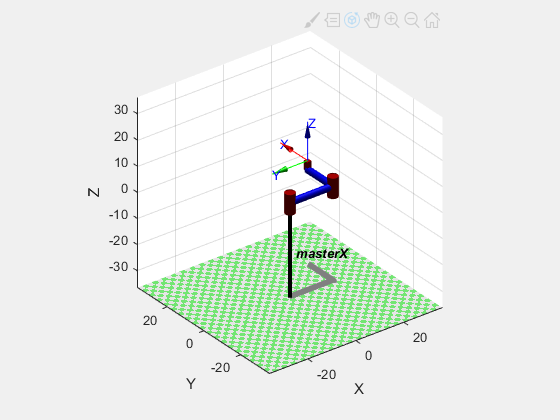

Tmaster = [deg2rad(0), deg2rad(90), spottingSWGCylinderExtension ];
modelMasterX.plot(Tmaster)

# Pattern Swing Model

%L1 = Link ([0 l1 0 pi/2],'standard');
%L1.isrevolute
%L1.qlim =  pi/180*[-180 18

%[theta d a alpha sigma offset]
%sigma == 1, prismatic
%sigma == 0, revolute
link1 = Link( [ deg2rad(0), 0, 32.75, 0, 0, 0], 'standard' );
link1.qlim = pi/180 * [-60 60];

link2 = Link( [ deg2rad(-90), 0, 20.25, 0, 0, 0], 'standard' );
link2.qlim = pi/180 * [-95 85];
%39.486
link3 = Link( [ deg2rad( 0), 0, 0, 0, 1, 0], 'standard' );
link3.qlim = [ 0 9.5];

link4 = Link( [ deg2rad(0), 0, 32.75, 0, 0, 0], 'standard' );
link4.qlim = pi/180 * [ -60 60];


modelSlaveX = SerialLink( [link1, link2, link3, link4], 'name', 'slaveX')

 
modelSlaveX = 
 
slaveX:: 4 axis, RRPR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|      32.75|          0|          0|
|  2|         q2|          0|      20.25|          0|          0|
|  3|          0|         q3|          0|          0|          0|
|  4|         q4|          0|      32.75|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


%inputs forward kinematics
patternSWGCylinderExtension = 9.5/2 %limit is 0 to 9.5

patternSWGCylinderExtension = 4.7500

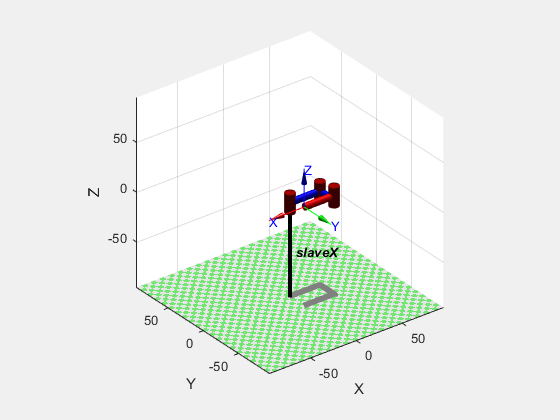

Tslave = [ deg2rad( 0 ), deg2rad(-90), patternSWGCylinderExtension, deg2rad( -90 )];
modelSlaveX.plot(Tslave)

%input inverse kinematic
slaveHoleX = 23

slaveHoleX = 23

version = 1;
height = 38.188 * cos( deg2rad( 70 ))

height = 13.0611

if version == 1
    patternSWGCylinderExtension = sqrt( slaveHoleX * slaveHoleX + height*height ) - link2.a
else
    carriageToGun = 7.061;
    carriageToSpottingCylinder = 0.313;
    patternSWGCylinderExtension = slaveHoleX - link2.a - masterHoleX + carriageToGun+(carriageToGun-carriageToSpottingCylinder)
end

patternSWGCylinderExtension = 6.1998

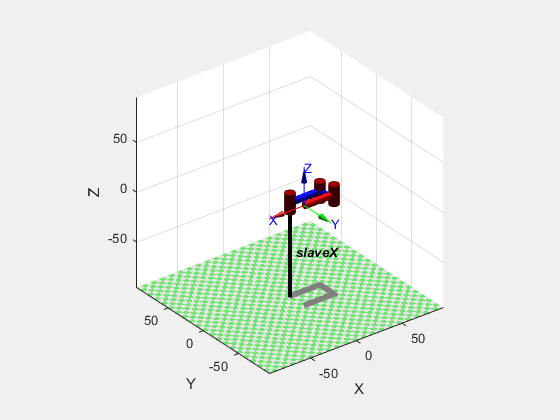


Tslave = [ deg2rad( 0 ), deg2rad(-90), patternSWGCylinderExtension, deg2rad( -90 )];
modelSlaveX.plot(Tslave)